SimulationName='simulation_test_lifetime_distribution_20220715';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/'

cd(filepath)

% spc_openCurves('/Volumes/yaochen/Active/Pingchuan/2020FL/0922AKARFLEmx1Cre001/0922AKARFLEmx1Cre001FLIM016.mat',1)
load('PKA_simulation_parameters_20220719')
p1_PKA

p1_PKA = 0.6046

p2_PKA

p2_PKA = 0.3954

tau1_PKA

tau1_PKA = 2.1400

tau2_PKA

tau2_PKA = 0.6900

samplesize_PKA

samplesize_PKA = 816397


load('prf_PKA.mat')
prf_peak_PKA=find(prf==max(prf))

prf_peak_PKA = 53


PKA_PopulationName='PKA_population_20220719'

PKA_PopulationName = 'PKA_population_20220719'

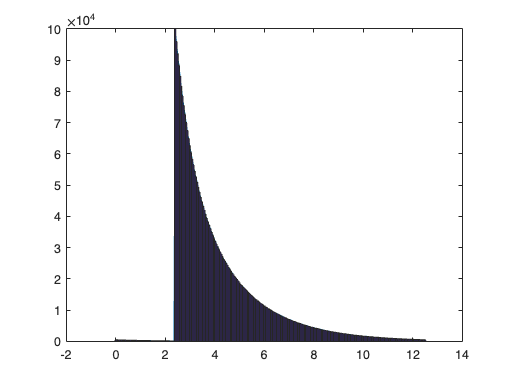

     3231724



GenPop256_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

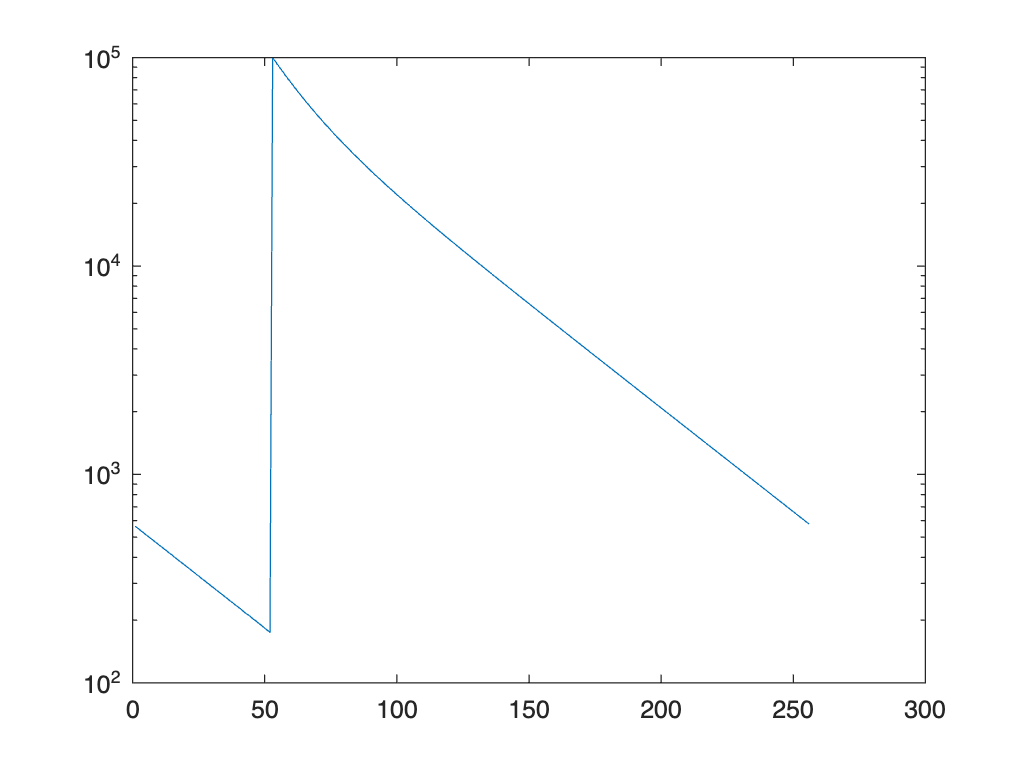

load('PKA_population_20220719.mat')
figure
semilogy(counts)

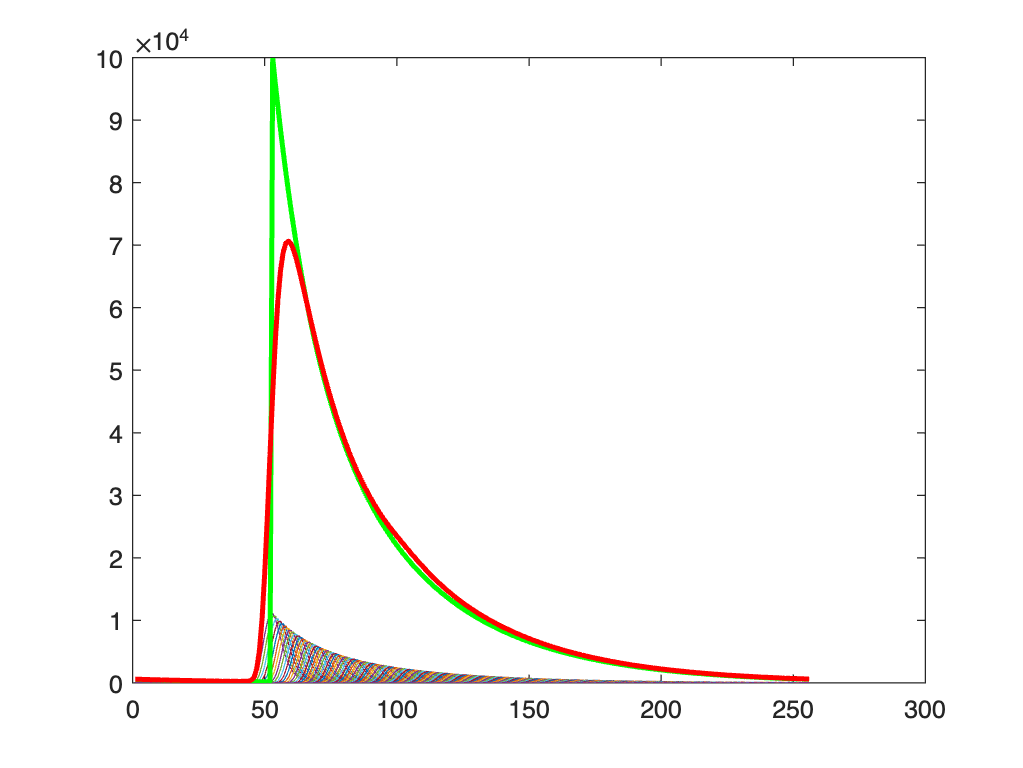


x_i=(1:1:256)-prf_peak_PKA;
x=x_i*(12.5/256);
xsim=linspace(0,12.5,256);
[n,xout]=hist(Population, xsim);

    
for i=1:256
    eval(['n_c_',num2str(i),'=zeros(1,256);'])
    n_i = n(i)*prf;
    x_c=x_i+i; 
    
    for j=1:size(x_c,2)
        if x_c(j)<=0
           x_c(j)=x_c(j)+256;  
        end
        
        if x_c(j)>256
            x_c(j)=x_c(j)-256;
        end
        
    end
    eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
end
figure
xlabel('Channels')
ylabel('Photon Count')
for i=1:256
    eval(['plot(n_c_',num2str(i),')'])
    hold on
end
plot(n,'LineWidth',2,'Color','g')
hold on

n_c=zeros(1,256);
for i=1:256
    eval(['this_n=n_c_',num2str(i),';'])
    n_c=[n_c;this_n];
end
n_c_all=sum(n_c);
% eval(['hist_prf2_',num2str(k),'=n_c_all;'])

plot(n_c_all,'LineWidth',2,'Color','r');
hold off

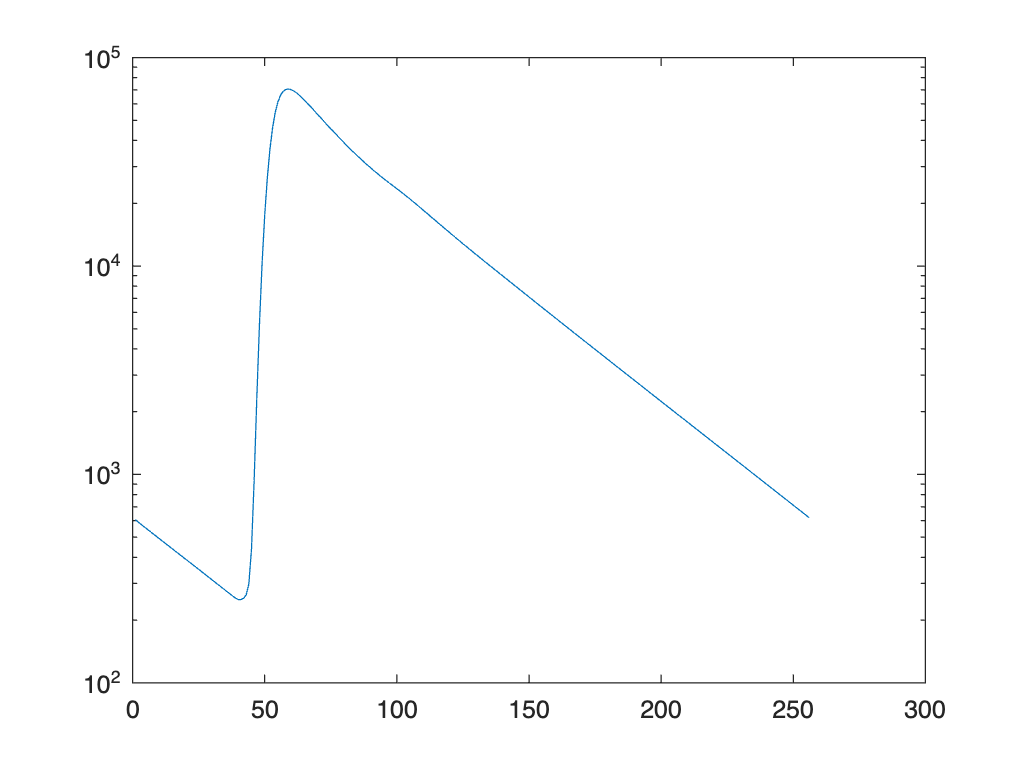

figure
semilogy(n_c_all)


n_c_all_norm=n_c_all/max(n_c_all);

mkdir([filepath,'/PKA_sensoronly_0719/']);

AF=0; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach_noauto(samplesize_PKA,0,AF,prf_peak_PKA,PKA_PopulationName, 'prf_PKA.mat', 'autofluorescence.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/PKA_sensoronly_0719/',num2str(j)];
    save(samplename,'n','xout');
end

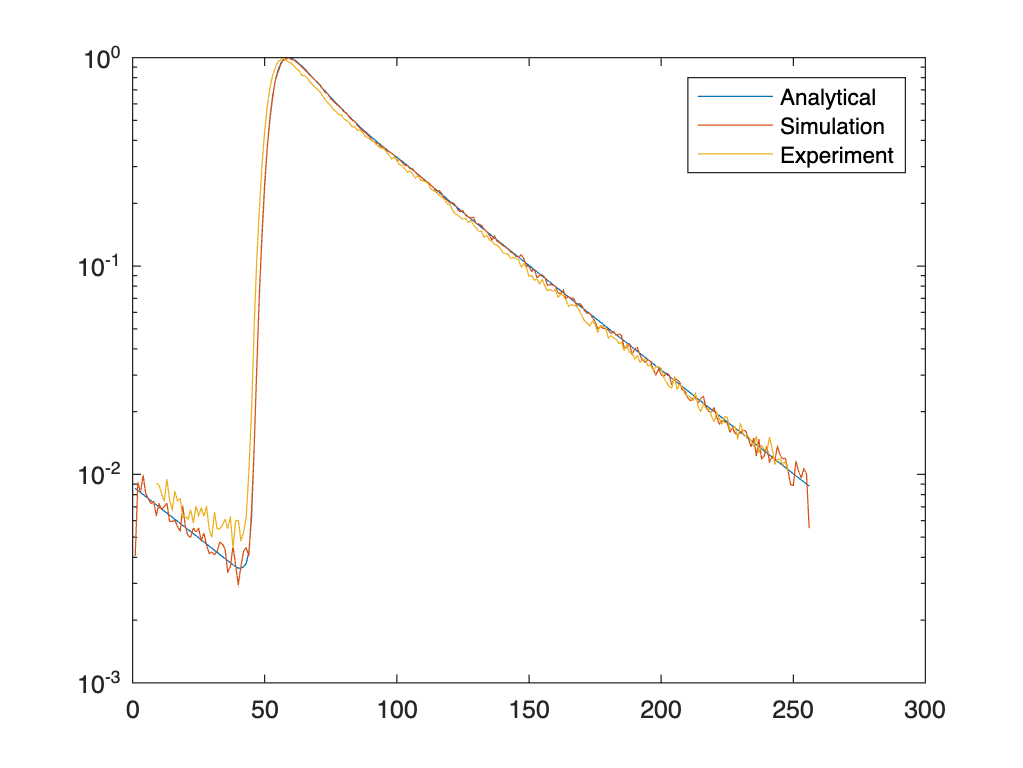

load([filepath,'/PKA_sensoronly_0719/1.mat'])
n_exp_PKA=n_exp_PKA/(max(n_exp_PKA));

n_sim=n/max(n);
figure
semilogy(n_c_all_norm)
hold on
semilogy(n_sim)
hold on
semilogy(n_exp_PKA)
legend('Analytical','Simulation','Experiment')


chan=1;
lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*n_c_all;
empirical_lft_analytical=sum(weight_n_lft)/sum(n_c_all)

empirical_lft_analytical = 4.4342


    cd([filepath,'/PKA_sensoronly_0719/']);
    matfiles = dir('*.mat');
    
    p=[];
    TauTrunc=[];
    chi2=[];
    avgTau=[];
    emp_lft=[];
    emp_lftTrunc=[];
    
    
    for j=1:50
        filename = matfiles(j).name;
        load(filename);
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*n;
%         empirical_lft=sum(weight_n_lft)/sum(n)+(figureoffset-spc.switchess{1,1}.figOffset); % prf peak at 53. 53*12.5/256=2.5879
        empirical_lft=sum(weight_n_lft)/sum(n);

        p(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2(j)=spc.fits{chan}.redchisq; %chi2
        avgTau(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft(j)=empirical_lft; % empirical lft
        emp_lftTrunc(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
    end

fraction of photons from SHG: 2.076e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0749e-10
fraction of photons from SHG: 2.0778e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0762e-10
fraction of photons from SHG: 2.0767e-10
fraction of photons from SHG: 2.0766e-10
fraction of photons from SHG: 2.078e-10
fraction of photons from SHG: 2.0775e-10
fraction of photons from SHG: 2.0771e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0774e-10
fraction of photons from SHG: 2.0763e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0777e-10
fraction of photons from SHG: 2.0769e-10
fraction of photons from SHG: 2.0787e-10
fraction of photons from SHG: 2.0774e-10
fraction of photons from SHG: 2.0775e-10
fraction of photons from SHG: 2.0765e-10
fraction of photons from SHG: 2.0759e-10
fraction of photons from SHG: 2.077e-10
fraction of photons

    
%     savename=[filepath,'simulation_result_PKA_20220718_3'];
%     save(savename,'p','TauTrunc','chi2','avgTau','emp_lft','emp_lftTrunc');

 spc.lifetimes{1}=n_c_all;

spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

ans = 0.5982

spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

ans = 0.4018

spc.fits{1,1}.beta5

ans = -1.1632e-04

spc.fits{1,1}.beta6

ans = 1.6909e-04

spc.switchess{1,1}.figOffset

ans = 1.9745